用误差条形图和散点对两组采样数据进行比较，并显示 t test p 值

## 语法

## 示例

## 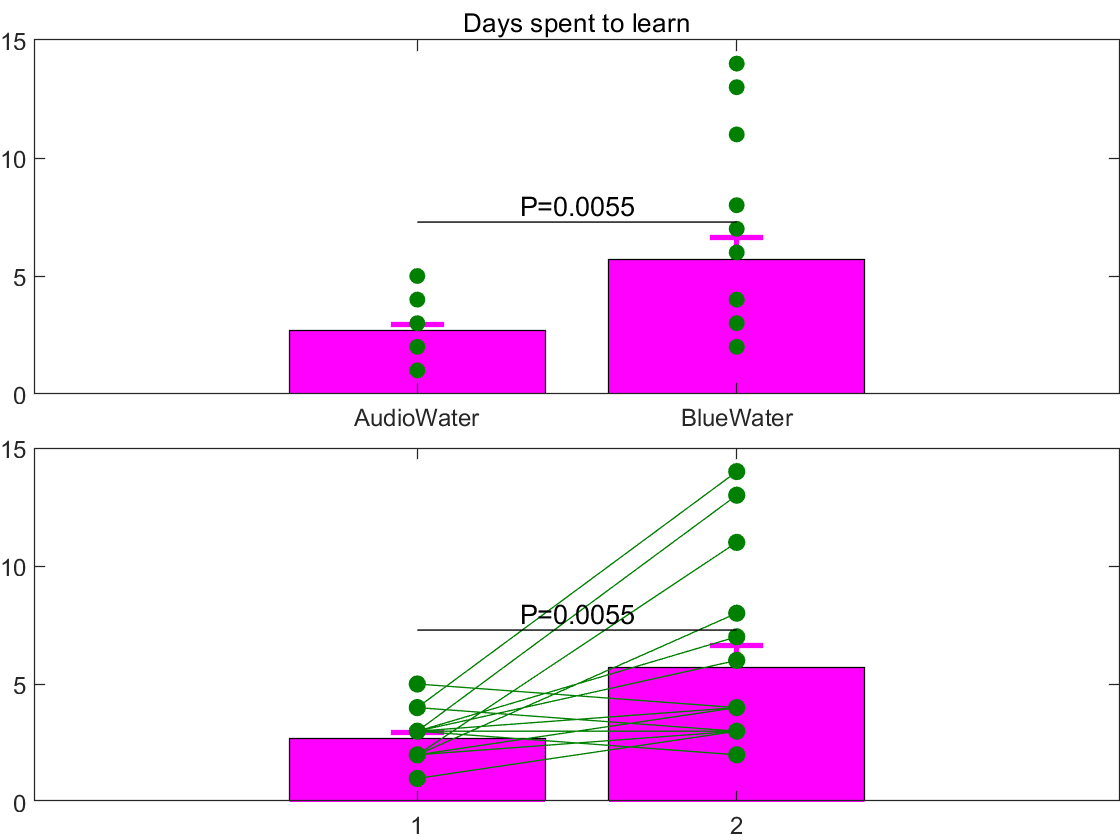

## 输入参数

DataA, DataB double，用于比较的数据采样点

UniExp.Flags.ScatterLink，指定此旗帜以将一一对应匹配的两组数据样本点连接起来。显然，这要求DataA和DataB的元素数目相同。

Colors(2,3)double，指定条形和散点的RGB颜色，范围[0,1]。第1行指定条形颜色，第2行指定散点颜色。误差条颜色和条形相同，连接线颜色和样本点相同。

**See also** [ttest2](matlab:doc ttest2)

function BarScatterCompare(DataA,DataB,varargin)
ScatterLink=false;
Colors=[1 0 1;0 0.5 0];
for V=varargin
	if isscalar(V{1})
		ScatterLink=V{1};
	else
		Colors=V{1};
	end
end
[Mean,Sem]=cellfun(@MATLAB.DataFun.MeanSem,{DataA;DataB});
bar(Mean,FaceColor=Colors(1,:));
HoldState=ishold;
hold on
errorbar([1;2],Mean,[],Sem,Color=Colors(1,:),LineStyle='none',CapSize=20,LineWidth=2);
if ScatterLink
	plot(repmat([1;2],1,numel(DataA)),[reshape(DataA,1,[]);reshape(DataB,1,[])],'-o',Color=Colors(2,:),MarkerFaceColor=Colors(2,:));
else
	[Xa,Ya]=PointDistribute(DataA(:));
	[Xb,Yb]=PointDistribute(DataB(:));
	scatter([Xa+1,Xb+2]',[Ya;Yb],[],Colors(2,:),'filled');
end
[~,P]=ttest2(DataA(:),DataB(:));
Line=max(Mean+Sem)*1.1;
plot([1 2],[Line Line],'k');
text(1.5,Line,sprintf(sprintf('P=%%.%uf',max(1-floor(log10(P)),0)),P),HorizontalAlignment='center',VerticalAlignment='bottom');
if ~HoldState
	hold off
end
end

function [Xs,Ys]=PointDistribute(Ys)
[~,~,G]=uniquetol(Ys,0.1);
[Xs,Ys]=splitapply(@GroupDistribute,Ys,G);
Xs=[Xs{:}];
Ys=vertcat(Ys{:});
end
function [Xs,Ys]=GroupDistribute(Ys)
Xs=linspace(-0.5,0.5,numel(Ys)+2);
Xs={Xs(2:end-1)};
Ys={Ys};
end